% =========================================================================
% LARGE-FIELD NASTRAN PUNCH FILE SINGLE DMIG ASSEMBLER & VISUALIZER
% =========================================================================
clear; clc; close all;

% --- User Configuration ---
pchFileName = 'plustenshellK_DMIG_AX.pch';  % Name of your punch file
targetMatrix = 'KAAX';                      % Matrix target from your file

% 1. Open the File
fid = fopen(pchFileName, 'r');
if fid == -1
    error('Could not open file: %s. Check the file name or folder path.', pchFileName);
end

rawEntries = []; % To store: [GJ, CJ, GI, CI, RealValue]
currentCol_GJ = NaN;
currentCol_CJ = NaN;
matrixActive = false;

% 2. Scan the File Line-by-Line
while ~feof(fid)
    line = fgetl(fid);
    
    % Skip comments or empty rows
    if isempty(line) || startsWith(strtrim(line), '$')
        continue;
    end
    
    % Track Matrix Blocks (Header Card 1)
    % Example: DMIG    KAAX           0       6       2       0       0             609
    if startsWith(line, 'DMIG ') || startsWith(line, 'DMIG,')
        cleanLine = strrep(line, ',', ' ');
        tokens = strsplit(strtrim(cleanLine));
        if length(tokens) >= 2 && strcmp(tokens{2}, targetMatrix)
            matrixActive = true;
        else
            matrixActive = false; 
        end
        continue;
    end
    
    % Parse inside target block
    if matrixActive
        % Track Column Headers (Header Card 2)
        % Example: DMIG* KAAX                   1       1
        if startsWith(line, 'DMIG*')
            % Verify this line belongs to our target matrix
            if contains(line, targetMatrix)
                % Extract Column Grid (GJ) and Column Component (CJ) from the end of the line
                % Field 5 (cols 41-56) and Field 6 (cols 57-72)
                if length(line) >= 72
                    currentCol_GJ = str2double(line(41:56));
                    currentCol_CJ = str2double(line(57:72));
                else
                    % Fallback if fields are shorter/shifted slightly due to tabbing
                    tokens = strsplit(strtrim(line));
                    currentCol_GJ = str2double(tokens{end-1});
                    currentCol_CJ = str2double(tokens{end});
                end
            end
            continue;
        end
        
        % Check if it's a Data Continuation Row
        % Example: * 1       1          1.1360042735D10
        if startsWith(line, '*') && length(line) >= 40
            try
                % Strict fixed-field slicing based on Nastran standard
                % Field 2 (cols 9-24): Row Grid ID (GI)
                % Field 3 (cols 25-40): Row Component DOF (CI)
                row_GI = str2double(line(9:24));
                row_CI = str2double(line(25:40));
                
                % Field 4 (cols 41-72): Double-precision value
                valStr = line(41:min(72, length(line)));
                valStr = strrep(valStr, 'D', 'E'); % Convert Nastran 'D' to MATLAB 'E'
                val = str2double(strtrim(valStr));
                
                if ~isnan(row_GI) && ~isnan(row_CI) && ~isnan(val) && ~isnan(currentCol_GJ)
                    rawEntries = [rawEntries; currentCol_GJ, currentCol_CJ, row_GI, row_CI, val]; %#ok<AGROW>
                end
            catch
                continue;
            end
        end
    end
end
fclose(fid);

if isempty(rawEntries)
    error('Matrix "%s" was not processed. Please check if the file name matches exactly.', targetMatrix);
end

% 3. Map Unique Structural Grid-DOF Keys to Sequential Indices
colsUnique = unique(rawEntries(:, 1:2), 'rows');
rowsUnique = unique(rawEntries(:, 3:4), 'rows');
allDOFs = unique([colsUnique; rowsUnique], 'rows');

numDOFs = size(allDOFs, 1);
matrixOut = zeros(numDOFs, numDOFs);

% 4. Matrix Assembly Loop
for k = 1:size(rawEntries, 1)
    [~, cIdx] = ismember(rawEntries(k, 1:2), allDOFs, 'rows');
    [~, rIdx] = ismember(rawEntries(k, 3:4), allDOFs, 'rows');
    
    v = rawEntries(k, 5);
    
    matrixOut(rIdx, cIdx) = v;
    if rIdx ~= cIdx
        matrixOut(cIdx, rIdx) = v; % Apply structural symmetry condition
    end
end

fprintf('--- Structural Assembly Complete ---\n');

--- Structural Assembly Complete ---


fprintf('Matrix Identifier: %s\n', targetMatrix);

Matrix Identifier: KAAX


fprintf('Total Unified DOFs: %d x %d\n\n', numDOFs, numDOFs);

Total Unified DOFs: 924 x 924



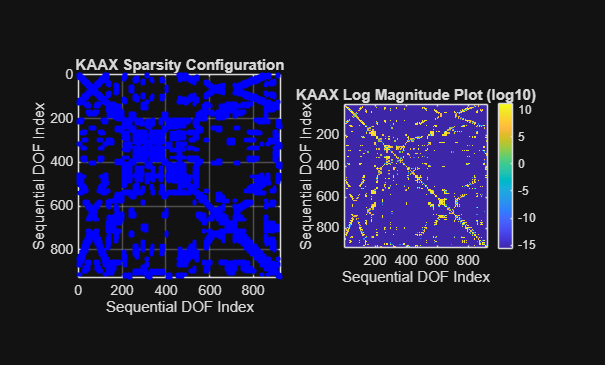


% 5. Matrix Visualizer Engine
figure('Name', ['Nastran Plot: ' targetMatrix], 'NumberTitle', 'off');

% Subplot 1: Spy Plot Pattern
subplot(1, 2, 1);
spy(matrixOut, 'b', 8);
title(sprintf('%s Sparsity Configuration', targetMatrix));
xlabel('Sequential DOF Index');
ylabel('Sequential DOF Index');
grid on;

% Subplot 2: Log-Scale Value Heat Map
subplot(1, 2, 2);
imagesc(log10(abs(matrixOut) + eps));
colorbar;
title(sprintf('%s Log Magnitude Plot (log10)', targetMatrix));
xlabel('Sequential DOF Index');
ylabel('Sequential DOF Index');
axis square;


% Export data globally back to active workspace
assignin('base', targetMatrix, matrixOut);
assignin('base', [targetMatrix '_DOF_Map'], allDOFs);
disp(['Variables assigned successfully to workspace.']);

Variables assigned successfully to workspace.
